5. Un diferenciador realiza la operación y(t) = dx(t)/dt, que en la frecuencia es la multiplicación por jw, por lo tanto la operación de diferenciación se puede ver como el filtrado con un filtro cuya función de transferencia es jw.	

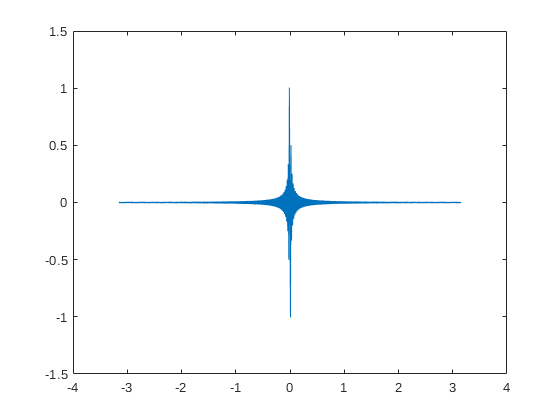

bound = [-pi,pi];
w     = bound(1)-1/100:1/100:bound(2)+1/100;
derivator = real(ftot(1i*w));
plot(w,derivator);

- Diseñe un filtro FIR de 41, 51 y 61 coeficientes que haga una operación de derivada. (puede utilizar cualquier ventana)

             Se crear un filtro de hamming muestreando 41,51,61 coeffiecientes. 

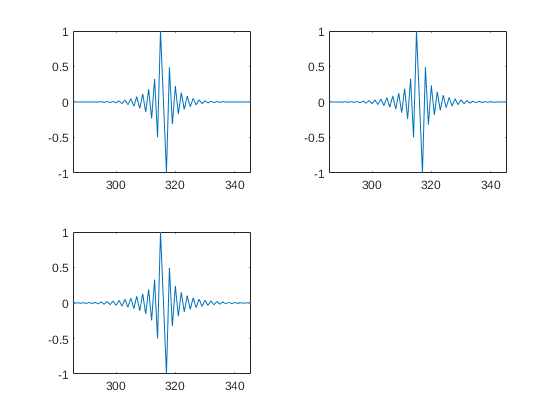

Coeff    = [41,51,61];
FIR      = zeros (length(Coeff),length(w));
%inserting hamming filtering
middle = (length(w))/2;
figure(1);
dt_fs = tiledlayout(2,2);
for n=1:1:3
    left   = int32((middle-Coeff(n)/2));
    right  = int32((middle+Coeff(n)/2));
    FIR(n,left:right) = hamming(Coeff(n)+1)';
    FIR(n,:) = derivator.*FIR(n,:);
    nexttile
    plot(FIR(n,:));
    axis([-30+middle middle+30 -1 1])
    %normalization
    FIR(n,:) = ttof(FIR(n,:))/max(ttof(FIR(n,:)));
end

2. Dada las aproximaciones con los filtros diferenciadores h1[n] = {-1,1}, h2[n] = {0.5, 0,-0,5}. Con el cero en el primer coeficiente en ambos filtros.   Obtenga de ambos su función de transferencia analítica.

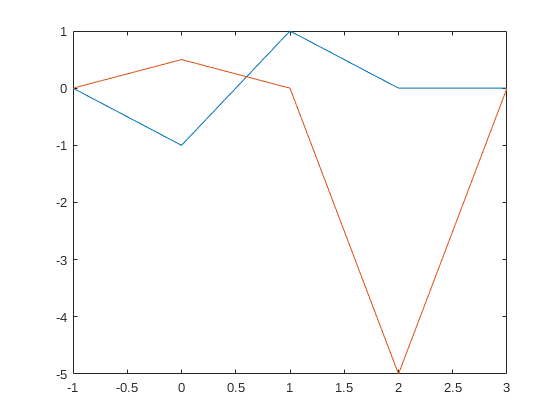

figure(3)
time = -1:1:3;
h_1 = [0,-1,1,0,0];
h_2 = [0,.5,0,-5,0];
plot(time,h_1);
hold on;
plot(time,h_2);
hold off;

3. Compare las funciones de transferencia obtenida por a) y b) y concluya que tanto se aproximan al derivador real.		

4. Introduzca una señal coseno en múltiplos de $\frac{\pi }{10}$ desde 0 a $\pi$ (es decir, su frecuencia angular discreta) a los filtros anteriores, y verifique a partir de las señales generadas por simulación si los filtros efectivamente realizan la operación de derivación: justifique sus conclusiones. (grafique la señal de salida y la entrada en un mismo cuadro para apoyar sus observaciones)	


$$T=\frac{\pi }{10}$$



$$f=\frac{10}{\pi }$$



$$\omega =2\pi \frac{10}{\pi }$$


signal = cos(10*w);

Aplicacion de filtro derivador

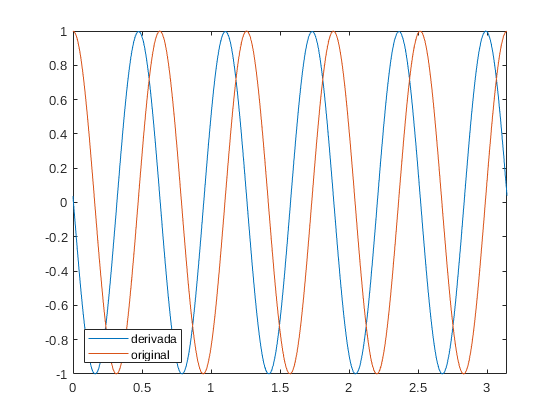

figure(6)
derivative= real(ftot(ttof(signal).*FIR(1,:)));
derivative= rescale(derivative,-1,1); 
plot(w,derivative);
hold on;
plot(w,signal);
hold off;
axis([0 pi -1 1])
legend({'derivada','original'},'Location','southwest')

### Observaciones

Pese al filtro estar normalizado en frecuencia y tener un factor de coefficientes considerables fue necesario un rescalamiento de la señal, dado que la señal derivada salia muy pequeña. 